# **JacobiCD**

Jacobi elliptic function cd

## Definition


$$\mathrm{cd}\left(x\left|m\right.\right)\equiv \frac{\mathrm{cn}\left(x|m\right)}{\mathrm{dn}\left(x|m\right)}$$



$$\mathrm{cd}\left(x,k\right)\equiv \mathrm{cd}\left(x\left|k^2 \right.\right)$$


where *cn* and *dn* are Jacobi elliptic function, $-\infty <x<\infty$, $-\infty <m<\infty$ is the parameter and $\left|-\infty <k<\infty \right.$ is the modulus. For the specified domain, the  codomain of *cd *are real numbers.

Basic features:

$\textrm{cd}\left(x+4K\left(m\right)\left|m\right.\right)=\textrm{cs}\left(x\left|m\right.\right)$  (periodic) ,  $\mathrm{cd}\left(-x\left|m\right.\right)=\mathrm{cd}\left(x\left|m\right.\right)$ (even)

Special values:


$$\mathrm{cd}\left(0\left|m\right.\right)=1$$


$\mathrm{cd}\left(x|0\right)=\mathrm{cos}\left(x\right)$,  $\mathrm{cd}\left(x|1\right)=1$

Identities:


$$\mathrm{cd}\left(x\left|m\right.\right)=\mathrm{dc}\left(x\sqrt{m}\left|m^{-1} \right.\right)$$


## Syntax

Y = JacobiCD(X,K)

y = jcd(x,k)

Y = mJacobiCD(X,M)

y = mjcd(x,m)

## Description

Y = JacobiCD(X,K) returns the Jacobi elliptic function $\mathrm{cd}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. JacobiCD is the wrapper function which calls the functions* jcd* element-wise via the function **ufun2**.

y = jcd(x,k) returns the Jacobi elliptic function $\mathrm{cd}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed. **jcd** calls the functions **sncndn **for calculation of *cn *and *dn*.

Y = mJacobiCD(X,M) returns the Jacobi elliptic function $\mathrm{cd}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. mJacobiCD is the wrapper function which calls the function mjcd element-wise via the function **ufun2**.

y = mjcd(x,m) returns the Jacobi elliptic function $\mathrm{cd}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed.   **mjcd** call the function **sncndn **for calculation of *cn *and *dn*.

**sncndn **implements the AGM transformation for simultaneously  computation of the functions *sn*, *cn*, *dn* . For $m>1$ the Jacobi's transformation is used [1,2].

## Precision

For  $\left|m\right|\le {10}^4$ the relative error of $\mathrm{cd}\left(x\left|m\right.\right)$ is less than ${10}^{-9}$ when $|x|<{10}^4$.

## **Numerical Examples**

**Salar input**

jcd(0.5,0.5)

ans = 0.9059

mjcd(0.5,0.5)

ans = 0.9356

fprintf('%.16g\n',mjcd(3,5))

1.001947552733332


*Note*. Exact value cd(3|5) =  `1.00194755273333``15`

**Vector of function values**

Create a column vector of domain values

x = (0:0.2:1)'

x =                    0
   0.200000000000000
   0.400000000000000
   0.600000000000000
   0.800000000000000
   1.000000000000000


Calculate the function values with k = 0.5

JacobiCD(x,0.5)

ans =    1.000000000000000
   0.984987945098656
   0.939828337175231
   0.864307153349669
   0.758568251941912
   0.623778370582396


Create a row vector of parameter values

m = -1.5:0.5:1

m =   -1.500000000000000  -1.000000000000000  -0.500000000000000                   0   0.500000000000000   1.000000000000000


Calculate the function values at x = 0.5

mJacobiCD(0.5,m)

ans =    0.733452306769205   0.777159420651966   0.825002451839855   0.877582561890373   0.935622687124812   1.000000000000000


Calculate the function values for two array arguments

mJacobiCD([2 1 -3],[1 2 3])

ans =    1.0e+02 *

   0.010000000000000   0.023829040168070  -1.786290339280530


mJacobiCD([2 1 -3]',[1 2 3]')

ans =    1.0e+02 *

   0.010000000000000
   0.023829040168070
  -1.786290339280530


**Matrix of function values**

Create a matrix of domain values

X=[-1 0 1 2; 2 3 4 8];

Calculate the function values with parameter m = 2.

mJacobiCD(X,2)

ans =    2.382904016806990   1.000000000000000   2.382904016806990  -1.265513478747450
  -1.265513478747450  -1.079746891958752  10.591101288770865  -1.009076396430391


Calculate the function values for two matrix arguments.

JacobiCD([2 1 -3; -1 2 3],[1 2 3; -1 2 3])

ans =    1.000000000000000  -3.247824543831676  -1.275430492234766
   1.000000000000000  -1.174987014877603  -1.275430492234766


## **Graphs of Jacobian Elliptic Functions sn**

**Example 1**

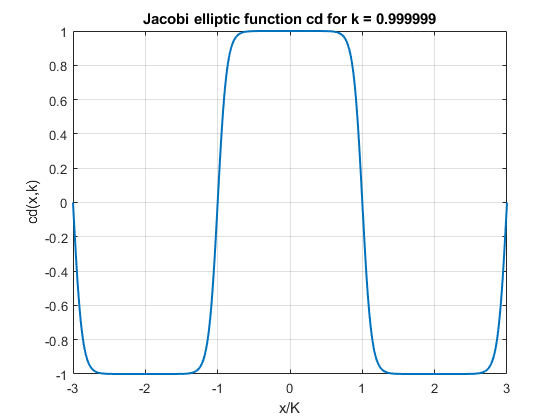

figure
x=-3:0.01:3;
k = 0.999999;
plot(x,JacobiCD(elK(k)*x,k),'LineWidth',1.5)
xlabel('x/K')
ylabel('cd(x,k)')
title(sprintf('Jacobi elliptic function cd for k = %g',k))
grid on

**Example 2**

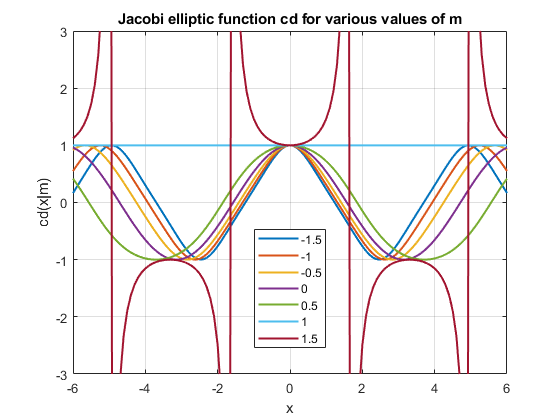

figure
X = -6:0.1:6;
M = -1.5:0.5:1.5;
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiCD(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -3 3])
grid on
legend(clg,'Location','Best')
title('Jacobi elliptic function cd for various values of m')
xlabel('x')
ylabel('cd(x|m)')

**Example 3**

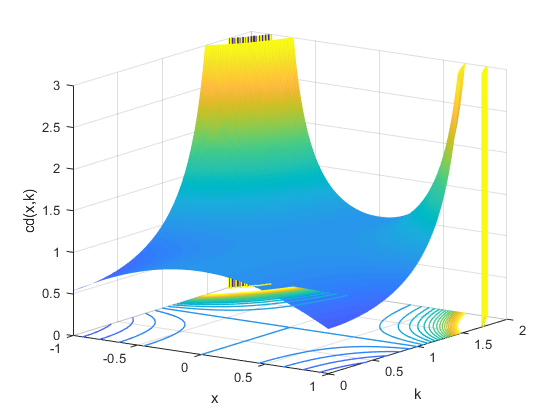

figure
x=-1:0.01:1;
k=0:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,JacobiCD(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 1;
hc.LevelList = 0:0.1:3;
caxis([0 3])
view([35 15]);
xlabel('x')
ylabel('k')
zlabel('cd(x,k)')
zlim([0 3])
grid on

**Example 4**

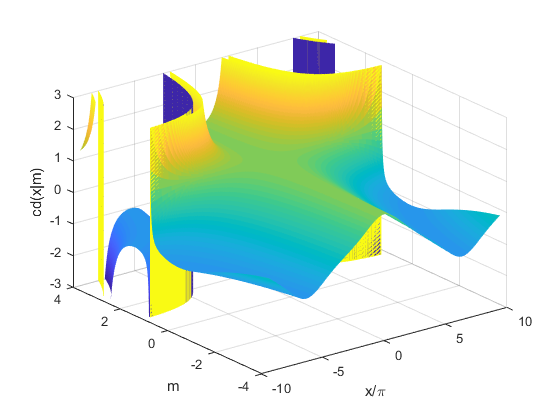

figure
x=-3:0.01:3;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
surface(pi*X,M,mJacobiCD(X,M),'EdgeColor','none')
view(3)
caxis([-3 3])
xlabel('x/\pi')
ylabel('m')
zlabel('cd(x|m)')
zlim([-3 3])
grid on

**Example 5**

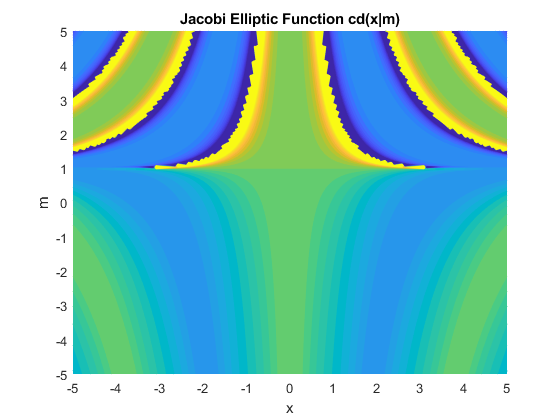

figure
f = @(x,m)mJacobiCD(x,m);
fcontour(f,'Fill','on','MeshDensity',200,'LevelList',-3:0.2:3)
title('Jacobi Elliptic Function cd(x|m)')
xlabel('x')
ylabel('m')

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions. Numerische Mathematik 7, 78-90, 1965

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also